# Sequence-to-Sequence Classification Using 1-D Convolutions

This example shows how to classify each time step of sequence data using a generic temporal convolutional network (TCN).

PRJ: see also NN models published here: [https://paperswithcode.com/paper/eegnet-a-compact-convolutional-network-for](https://paperswithcode.com/paper/eegnet-a-compact-convolutional-network-for) 

clear all; close all;

## Loading all the data

% SrcPath = '/home/peter/Projects/EEG/NN-classification/data/eyes';
SrcPath = '../data/eyes/Combined/';
SrcNamePattern={'*_EC.mat','*_EO.mat'};
ClassNames=categorical({'EC','EO'});

channelList = {'Fp1';'AF7';'AF3';'F1';'F3';'F5';'F7';'FT7';'FC5';'FC3';'FC1';'C1';'C3';'C5';'T7';'TP7';'CP5';'CP3';'CP1';'P1';'P3';'P5';'P7';'P9';'PO7';'PO3';'O1';'Iz';'Oz';'POz';'Pz';'CPz';'Fpz'; 'Fp2';'AF8';'AF4';'Afz';'Fz';'F2';'F4';'F6';'F8';'FT8';'FC6';'FC4';'FC2';'FCz';'Cz';'C2';'C4';'C6';'T8';'TP8';'CP6';'CP4';'CP2';'P2';'P4';'P6';'P8';'P10';'PO8';'PO4';'O2'};
elToConsider = {'Cz';'C3';'C4'};
elPositions = find(ismember(channelList, elToConsider)); % this may not always be used, but that's not a problem
srate = 256; % sampling frequency in Hz

files=cell(numel(SrcNamePattern),1);
for npat=1:numel(SrcNamePattern)
    files{npat} = dir([ SrcPath filesep SrcNamePattern{npat}]); 
    for nfile=1:numel(files{npat})
        files{npat}(nfile).data=load( ...
            [ files{npat}(nfile).folder filesep ...
              files{npat}(nfile).name ]).dataRest(elPositions,:);
        files{npat}(nfile).class=ClassNames(npat);
    end
end
files = vertcat(files{:}); % flatten to have all files together

Data organization and splitting into training/validation/testing:

Inputs = {};
Outputs = {};
nClasses = numel(categories(ClassNames));
chunkSize = 4*srate; % 4 seconds;

for nfile = 1:numel(files)
    nChunks=floor(size(files(nfile).data,2)/chunkSize);
    for i=1:nChunks
        Inputs{end+1}=files(nfile).data(:,((i-1)*chunkSize+1):(i*chunkSize));
        Outputs{end+1}=repmat(files(nfile).class,[1,chunkSize]);
    end
end


Divide data randomly into **train**, **test** and **validation** datasets

%PRJ - todo: load all data first and then divide it using 'dividerand' to
%define train, test and validation datasets
nChunks=numel(Outputs);
[trainInd,valInd,testInd] = dividerand(nChunks,0.8,0,0.2); % remove validation proportion
 
InTrain = Inputs(1,trainInd);
OutTrain= Outputs(1,trainInd);
% InValid = Inputs(1,valInd);
% OutValid= Outputs(1,valInd);
InTest  = Inputs(1,testInd);
OutTest= Outputs(1,testInd);


## Define Deep Learning Model

The main building block of a TCN is a dilated causal convolution layer, which operates over the time steps of each sequence. In this context, "causal" means that the activations computed for a particular time step cannot depend on activations from future time steps. 

To build up context from previous time steps, multiple convolutional layers are typically stacked on top of each other. To achieve large receptive field sizes, the dilation factor of subsequent convolution layers is increased exponentially, as shown in the following image. Assuming that the dilation factor of the k-th convolutional layer is $2^{\left(k-1\right)}$ and the stride is 1, then the receptive field size of such a network can be computed as $R=\left(f-1\right)\left(2^K -1\right)+1$, where $f$ is the filter size and $K$ is the number of convolutional layers. Change the filter size and number of layers to easily adjust the receptive field size and the number of learnable parameters as necessary for the data and task at hand.

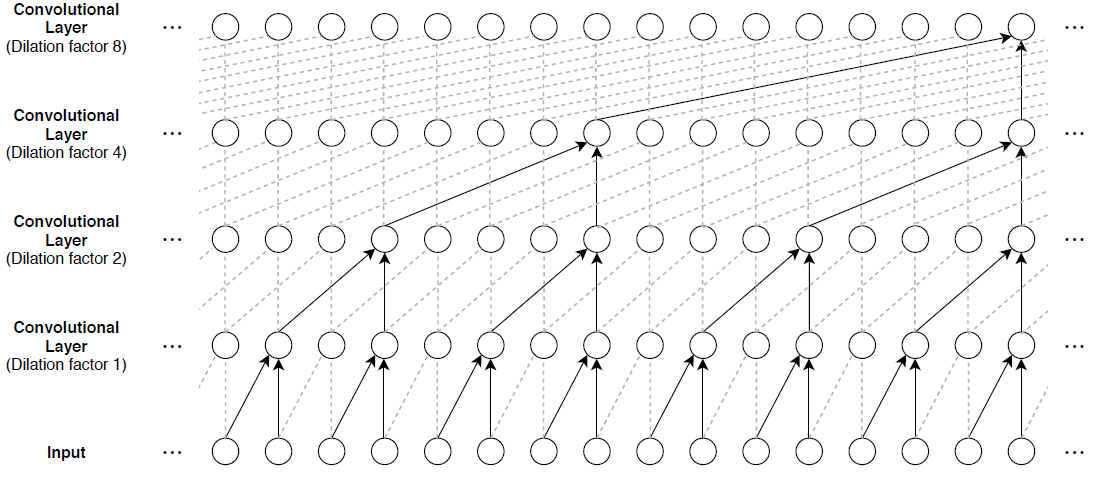

One of the disadvantages of TCNs compared to recurrent networks is that they have a larger memory footprint during inference. The entire raw sequence is required to compute the next time step. To reduce inference time and memory consumption, especially for step-ahead predictions, train with the smallest sensible receptive field size $R$ and perform prediction only with the last $R$ time steps of the input sequence.

The general TCN architecture (as described in [1]) consists of multiple residual blocks, each containing two sets of dilated causal convolution layers with the same dilation factor, followed by normalization, ReLU activation, and spatial dropout layers. The network adds the input of each block to the output of the block (including a 1-by-1 convolution on the input when the number of channels between the input and output do not match) and applies a final activation function.

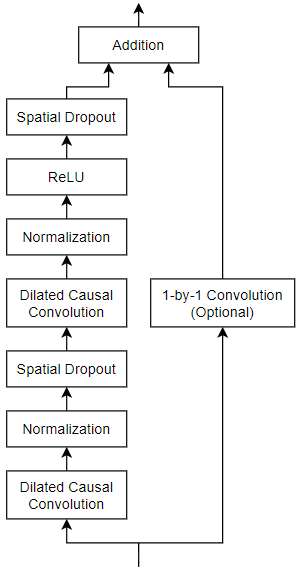

Define a network containing four of these residual blocks in series, each with double the dilation factor of the previous layer, starting with a dilation factor of 1. For the residual blocks, specify 64 filters for the 1-D convolutional layers with a filter size of 5 and a dropout factor of 0.005 for the spatial dropout layers. For spatial dropout, use the custom layer `spatialDropoutLayer`, attached to this example as a supporting file. To access this layer, open this example as a live script.

numFilters = 16; %64;
numFeatures = numel(elToConsider);
filterSize = 5 ; %PRJ / 5;
dropoutFactor = 0.005;
numBlocks = 2; %PRJ/ 4;

layer = sequenceInputLayer(numFeatures,Normalization="rescale-symmetric",Name="input");
lgraph = layerGraph(layer);

outputName = layer.Name;

for i = 1:numBlocks
    dilationFactor = 2^(i-1);
    
    layers = [
        convolution1dLayer(filterSize,numFilters,DilationFactor=dilationFactor,Padding="causal",Name="conv1_"+i)
        layerNormalizationLayer
        spatialDropoutLayer(dropoutFactor)
        convolution1dLayer(filterSize,numFilters,DilationFactor=dilationFactor,Padding="causal")
        layerNormalizationLayer
        leakyReluLayer %reluLayer
        spatialDropoutLayer(dropoutFactor)
        additionLayer(2,Name="add_"+i)];

    % Add and connect layers.
    lgraph = addLayers(lgraph,layers);
    lgraph = connectLayers(lgraph,outputName,"conv1_"+i);

    % Skip connection.
    if i == 1
        % Include convolution in first skip connection.
        layer = convolution1dLayer(1,numFilters,Name="convSkip");

        lgraph = addLayers(lgraph,layer);
        lgraph = connectLayers(lgraph,outputName,"convSkip");
        lgraph = connectLayers(lgraph,"convSkip","add_" + i + "/in2");
    else
        lgraph = connectLayers(lgraph,outputName,"add_" + i + "/in2");
    end
    
    % Update layer output name.
    outputName = "add_" + i;
end

layers = [
    fullyConnectedLayer(nClasses,Name="fc")
    softmaxLayer
    classificationLayer];
lgraph = addLayers(lgraph,layers);
lgraph = connectLayers(lgraph,outputName,"fc");

View the network in a plot.

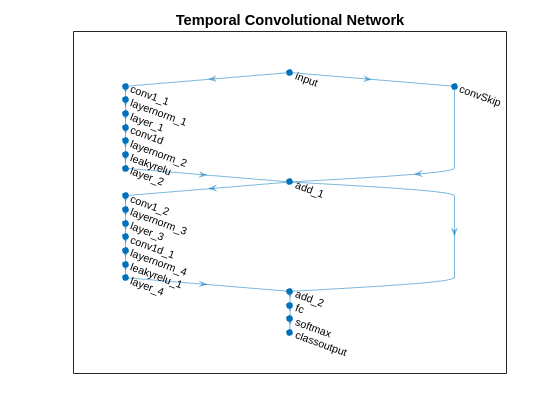

figure
plot(lgraph)
title("Temporal Convolutional Network")

## Specify Training Options

Specify a set of options used for training.

- Train for 60 epochs with a mini-batch size of 1.

- Train with a learning rate of 0.001.

- Display the training progress in a plot and suppress the verbose output.

options = trainingOptions("adam", ...
    MaxEpochs=500, ...
    miniBatchSize=50, ...
    Plots="training-progress", ...
    Verbose=true);

% options = trainingOptions("adam", ...
%     MaxEpochs=500, ...
%     miniBatchSize=50, ...
%     ValidationData={InValid,OutValid}, ...
%     ValidationFrequency=100, ...
%     Plots="training-progress", ...
%     Verbose=true);

## Train Model

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |       59.99% |       0.8846 |          0.0010 |
|       5 |          50 |       00:00:06 |       54.00% |       0.6829 |          0.0010 |
|      10 |         100 |       00:00:08 |       49.63% |       0.6746 |          0.0010 |
|      14 |         150 |       00:00:11 |       54.04% |       0.6380 |          0.0010 |
|      19 |         200 |       00:00:14 |       48.21% |       0.6313 |          0.0010 |
|      23 |         250 |       00:00:16 |       73.76% |       0.4953 |          0.0010 |
|      28 |         300 |  

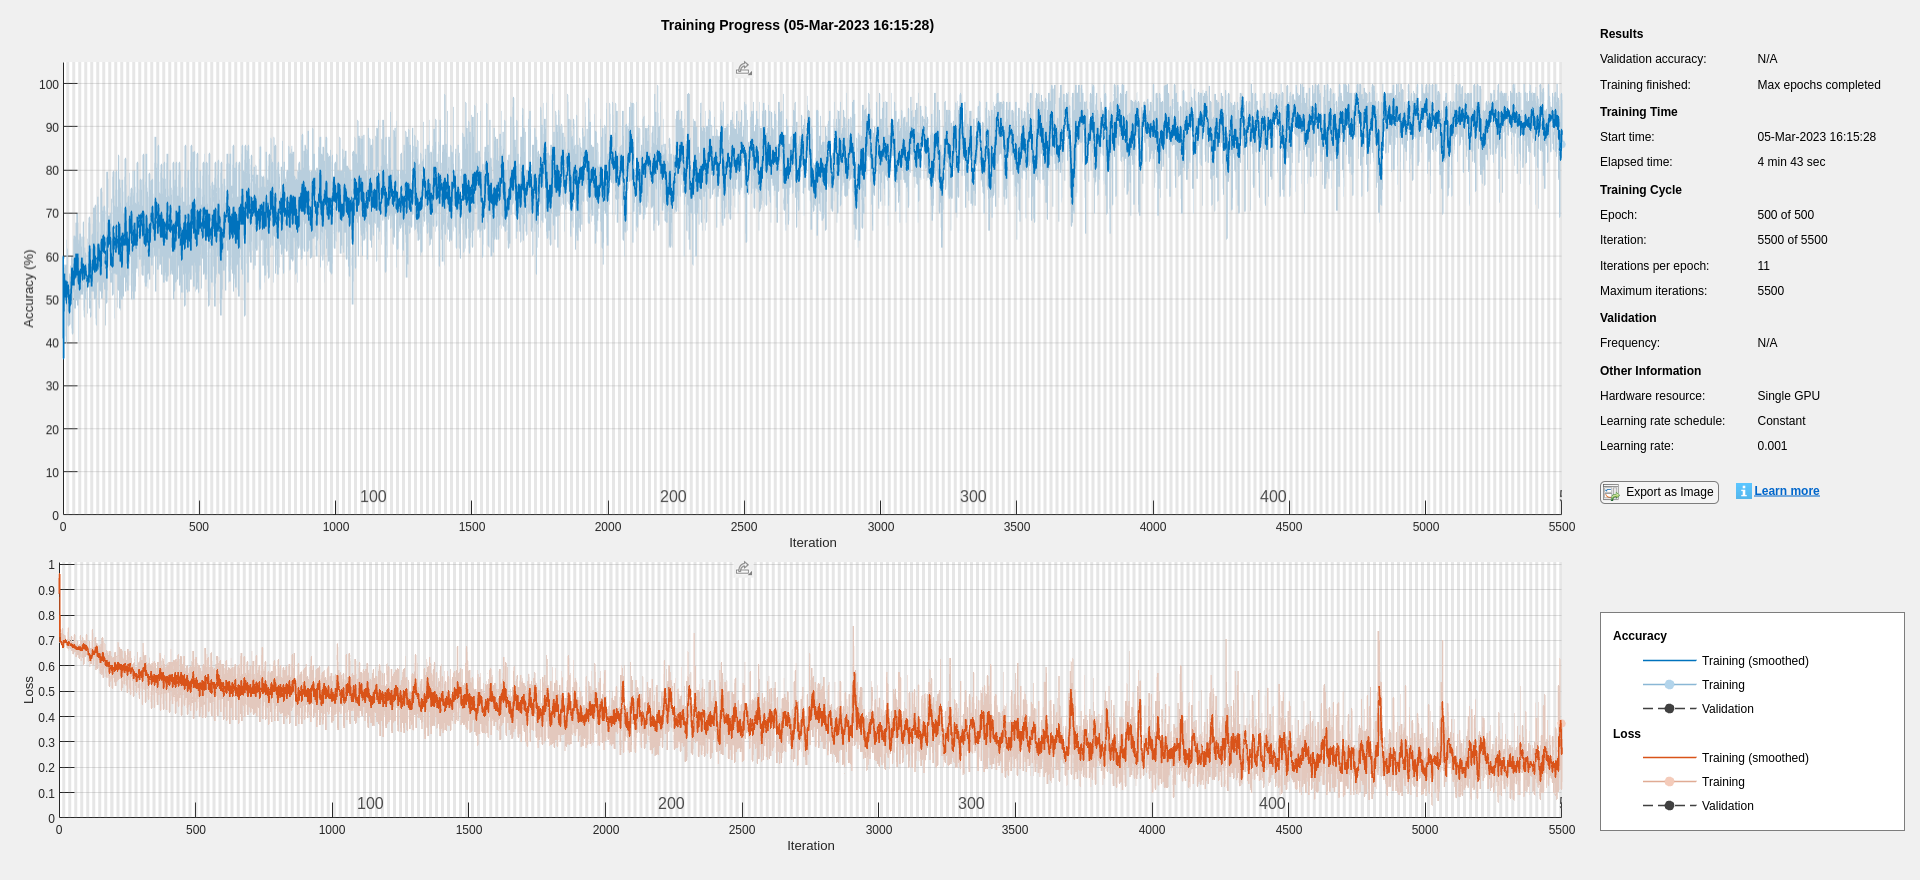

net = trainNetwork(InTrain,OutTrain,lgraph,options);

## Train more

Training on single GPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:01 |       94.57% |       0.1794 |          0.0010 |
|       5 |          50 |       00:00:04 |       90.07% |       0.2913 |          0.0010 |
|      10 |         100 |       00:00:06 |       81.78% |       0.5349 |          0.0010 |
|      14 |         150 |       00:00:09 |       94.70% |       0.1387 |          0.0010 |
|      19 |         200 |       00:00:11 |       93.74% |       0.1431 |          0.0010 |
|      23 |         250 |       00:00:14 |       79.27% |       0.3545 |          0.0010 |
|      28 |         300 |  

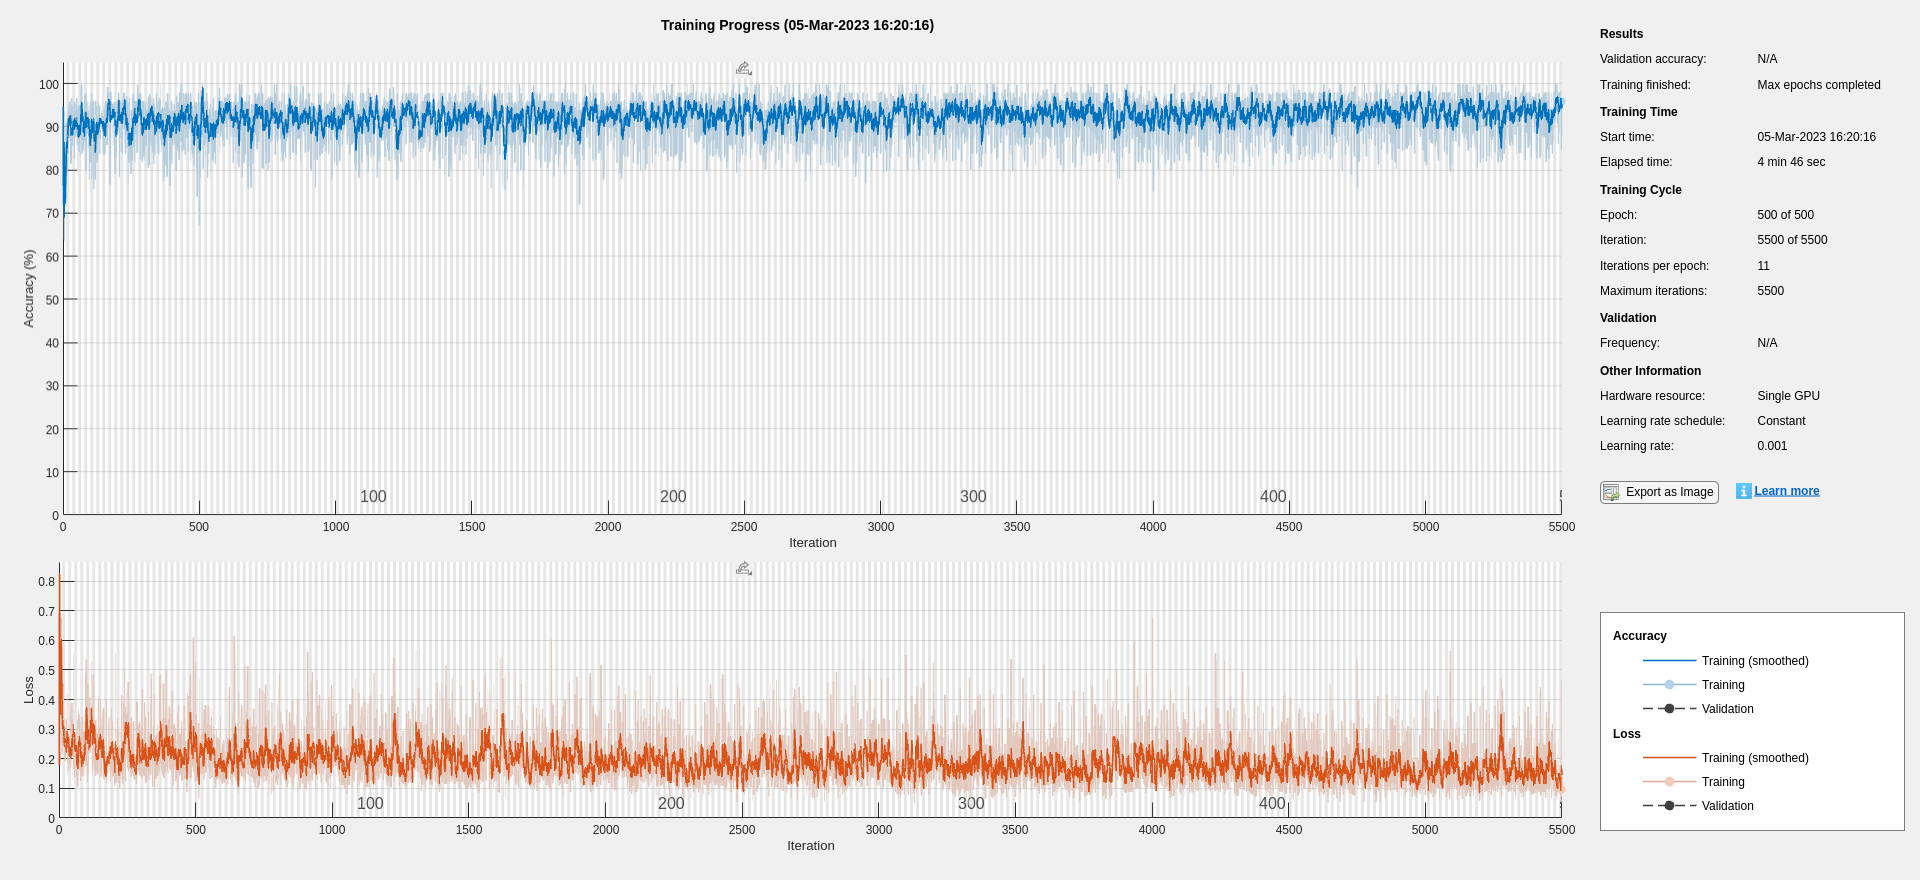

net = trainNetwork(InTrain,OutTrain,layerGraph(net),options);

save('net1.mat',"net");

## Test Model

Test the classification accuracy of the model by comparing the predictions on a held-out test set with the true labels for each time step. 

Use the trained network to make predictions by using the `classify` function.

OutPred = classify(net,InTest);

Visualize the predictions for **each sample** in a confusion matrix.

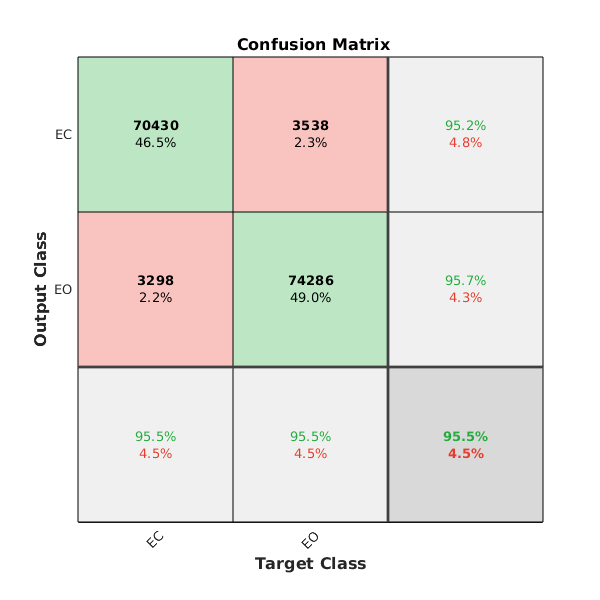

Pred = vertcat(OutPred{:});
True = vertcat(OutTest{:});
plotconfusion(True(:),Pred(:));

Visualize the predictions for **each sample** in a confusion matrix.

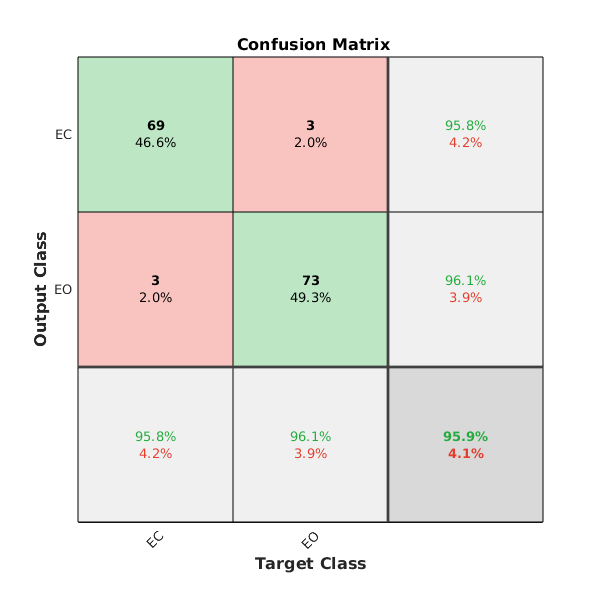

Pred = vertcat(OutPred{:});
True = vertcat(OutTest{:});
PredCount = countcats(Pred');
Predictions=1*(PredCount(1,:)<PredCount(2,:));
PredChunk = categorical(Predictions,[0 1],{'EC', 'EO'});
TrueChunk = True(:,1);
plotconfusion(TrueChunk(:),PredChunk(:));